# **Project**

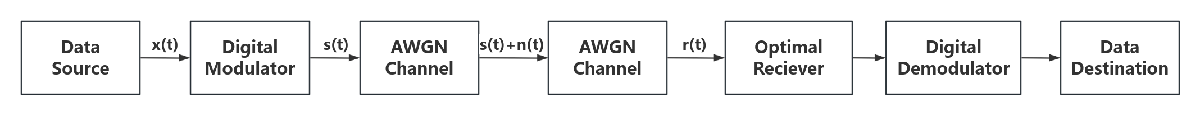

## **Inirialize simulation paremeters**

clear

%Set the simulation parameters
numbit=1000;                                           % Number of bits per packet
maxBitErrors = 1000;                                   % Maximum number of bit errors
maxNumBits = 1e7;                                      % Maximum number of bits transmitted

snrVec=(0:20)';                                        %Set the SNR(Eb/N0) vector from 0 to 20 dB

%Initialize the BER and error statistics arrays.
ber_2pam = zeros(length(snrVec),3);
ber_4pam = zeros(length(snrVec),3);
ber_qpsk = zeros(length(snrVec),3);
errorRate = comm.ErrorRate;

Simulate the communication link over the range of SNR. For each SNR value, the simulation runs until either `maxBitErrors` are recorded or the total number of transmitted bits exceeds `maxNumBits`.

## Task1

## PAM modulation

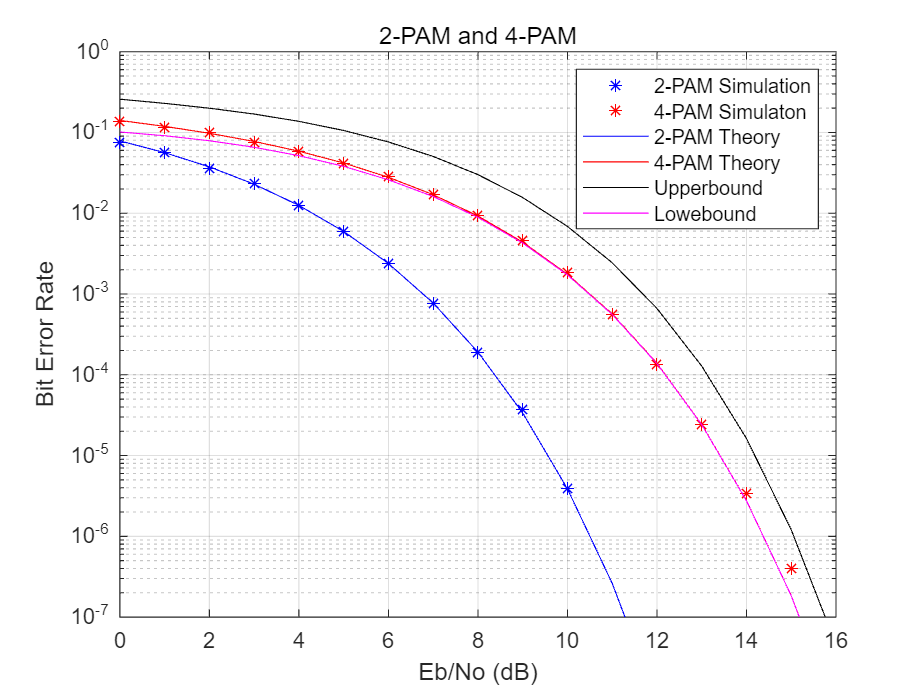

%2-PAM Modulation
M=2;                                                   % Modulation Order
k=log2(M);                                             % Bits per symbol
pamLevels = [-1 1];                                    % Gray mapping

for m = 1:length(snrVec)
    snr = snrVec(m);
    errorStats = zeros(1,3);
    
    while errorStats(2) <= maxBitErrors && errorStats(3) <= maxNumBits

        dataIn = randi([0,1],numbit,1);                % Generate binary data
        dataIn_integer=bit2int(dataIn,k);              % transform binary data to integer data
        Txsig = pammod(dataIn_integer,M,0,'gray');     % Apply 2-PAM modulation
        Rxsig = awgn(Txsig,snr+10*log10(k),'measured');% Pass the signal through AWGN channel

        %use ML reciever 
        distances = zeros(length(pamLevels), length(Rxsig));
        for i = 1:length(pamLevels)
             distances(i, :) = abs(Rxsig - pamLevels(i));
        end
        [~, minIndex] = min(distances, [], 1);
        Recsig = pamLevels(minIndex)';

        dataOut_integer = pamdemod(Recsig,M,0,'gray'); % Apply 2-PAM demodulation
        dataOut = int2bit(dataOut_integer,k);          % transform integer data to binary data
        errorStats = errorRate(dataIn,dataOut);        % Collect error statistics
    end
  
    ber_2pam(m,:) = errorStats;                        % Save BER data
    reset(errorRate)                                   % Reset the error rate calculator
end

%calculate theory BER for 2-PAM
bertheory_2pam= berawgn(snrVec,'pam',M,'nondiff');

%4-PAM Modulation
M=4;                      % Modulation Order
k=log2(M);                % bits per symbol
pamLevels = [-3 -1 1 3];  % Gray mapping

for m = 1:length(snrVec)
    snr = snrVec(m);
    errorStats = zeros(1,3);
    
    while errorStats(2) <= maxBitErrors && errorStats(3) <= maxNumBits

        dataIn = randi([0,1],numbit,1);                % Generate binary data
        dataIn_integer=bit2int(dataIn,k);              % transform binary data to integer data
        Txsig = pammod(dataIn_integer,M,0,'gray');     % Apply 4-PAM modulation
        Rxsig = awgn(Txsig,snr+10*log10(k),'measured');% Pass the signal through AWGN channel
      
        %use ML reciever 
        distances = zeros(length(pamLevels), length(Rxsig));
            for i = 1:length(pamLevels)
                 distances(i, :) = abs(Rxsig - pamLevels(i));
            end
        [~, minIndex] = min(distances, [], 1);
        Recsig = pamLevels(minIndex)';
        
        dataOut_integer = pamdemod(Recsig,M,0,'gray'); % Apply 4-PAM demodulation
        dataOut = int2bit(dataOut_integer,k);          % transform integer data to binary data
        errorStats = errorRate(dataIn,dataOut);        % Collect error statistics
    end
    
    ber_4pam(m,:) = errorStats;                        % Save BER data
    reset(errorRate)                                   % Reset the error rate calculator
end

%calculate theory BER for 4-PAM
bertheory_4pam= berawgn(snrVec,'pam',M,'nondiff');

snrVec_lin=db2pow(snrVec);
%calculate BER upper bound for 4-PAM
Upperbound=(3/8)*exp(-2/5*(snrVec_lin))+(1/4)*exp(-18/5*(snrVec_lin))-(1/8)*exp(-10*snrVec_lin);

%calculate BER lower bound for 4-PAM
x1 = sqrt(4/5*snrVec_lin);
x2 = 3*sqrt(4/5*snrVec_lin);
x3 = 5*sqrt(4/5*snrVec_lin);

lower_bound_Q1 = (x1./(sqrt(2*pi)*(1 + x1.^2))).*exp(-x1.^2/2);
lower_bound_Q2 = (x2./(sqrt(2*pi)*(1 + x2.^2))).*exp(-x2.^2/2);
lower_bound_Q3 = (x3./(sqrt(2*pi)*(1 + x3.^2))).*exp(-x3.^2/2);

Lowerbound = 3/4 * lower_bound_Q1 + 1/2 * lower_bound_Q2 - 1/4 * lower_bound_Q3;
%Lowerbound=snrVec_lin./(sqrt(2*pi*(1 + snrVec_lin.^2))).*exp(-snrVec_lin.^2/2);

%Plot the theoretical and simulated data on the same graph to compare results.
figure
semilogy(snrVec,ber_2pam(:,1),'b*',snrVec,ber_4pam(:,1),'r*');
hold on
semilogy(snrVec,bertheory_2pam,'b',snrVec,bertheory_4pam(:,1),'r');
semilogy(snrVec,Upperbound,'k');
semilogy(snrVec,Lowerbound,'m');
xlabel('Eb/No (dB)');
ylabel('Bit Error Rate');
title('2-PAM and 4-PAM');
legend('2-PAM Simulation','4-PAM Simulaton','2-PAM Theory','4-PAM Theory','Upperbound','Lowebound')
ylim([1e-7,1]);
grid on
hold off

## Task2

## QPSK modulation

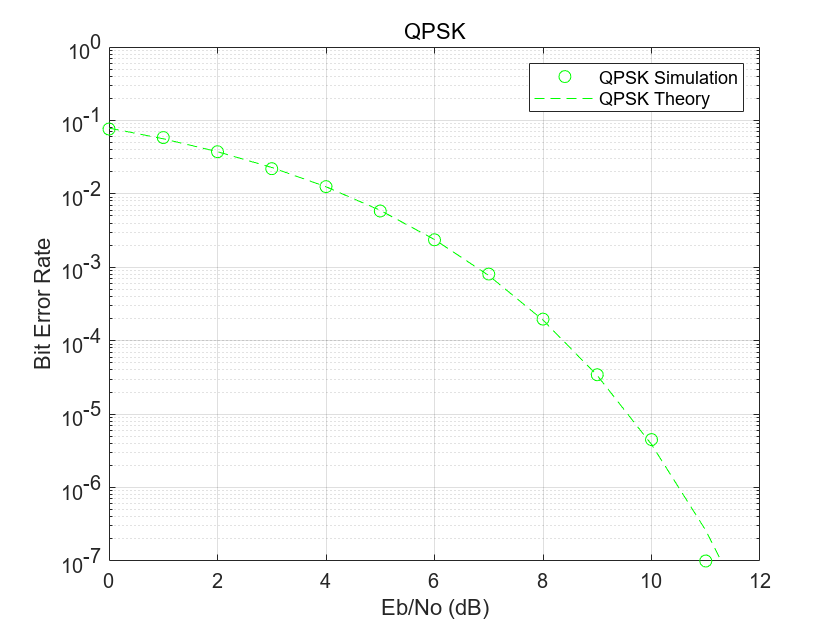

M=4;
k=log2(M);                                                                  % Bits per symbol
qpskLevels=[-0.7071-0.7071i,-0.7071+0.7071i,0.7071+0.7071i,0.7071-0.7071i]; % Gray mapping

for m = 1:length(snrVec)
    snr = snrVec(m);
    errorStats = zeros(1,3);
    
    while errorStats(2) <= maxBitErrors && errorStats(3) <= maxNumBits

        dataIn = randi([0,1],numbit,1);                                     % Generate binary data
        Txsig = pskmod(dataIn,M,pi/M,'gray',InputType='bit');               % Apply QPSK modulation
        Rxsig = awgn(Txsig,snr+10*log10(k), 'measured');                    % Pass the signal through AWGN channel

        %use ML reciever 
        distances = zeros(length(qpskLevels), length(Rxsig));
            for i = 1:length(qpskLevels)
                distances(i, :) = abs(Rxsig - qpskLevels(i));
            end
        [~, minIndex] = min(distances, [], 1);
        Recsig = qpskLevels(minIndex).';         
    
        dataOut = pskdemod(Recsig,M,pi/M,'gray',OutputType='bit');          % Applly QPSK demodulation
        errorStats = errorRate(dataIn,dataOut);                             % Collect error statistics
    end
  
    ber_qpsk(m,:) = errorStats;                                             % Save BER data
    reset(errorRate)                                                        % Reset the error rate calculator
end

%calculate theory BER for QPSK
bertheory_qpsk= berawgn(snrVec,'psk',M,'nondiff');

%Plot the theoretical and simulated data on the same graph to compare results.
figure
semilogy(snrVec,ber_qpsk(:,1),'go')
hold on
semilogy(snrVec,bertheory_qpsk,'g--')
xlabel('Eb/No (dB)');
ylabel('Bit Error Rate');
title('QPSK');
legend('QPSK Simulation','QPSK Theory')
ylim([1e-7,1]);
grid on
hold off

## Results 

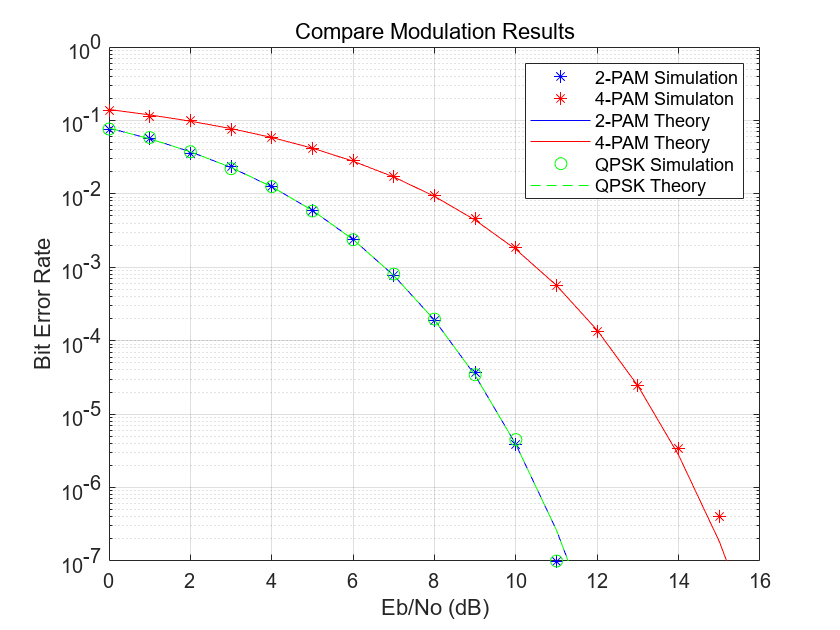

% Plot all data on the same graph to compare results
figure
semilogy(snrVec,ber_2pam(:,1),'b*',snrVec,ber_4pam(:,1),'r*');
hold on
semilogy(snrVec,bertheory_2pam,'b',snrVec,bertheory_4pam(:,1),'r');
semilogy(snrVec,ber_qpsk(:,1),'go')
semilogy(snrVec,bertheory_qpsk,'g--')
xlabel('Eb/No (dB)');
ylabel('Bit Error Rate');
title('Compare Modulation Results');
legend('2-PAM Simulation','4-PAM Simulaton','2-PAM Theory','4-PAM Theory','QPSK Simulation','QPSK Theory')
ylim([1e-7,1]);
grid on
hold off